rng(0);
clear;

Download the dataset comprising images of handwritten digits in http://yann.lecun.com/exdb/ mnist; this has been downloaded in the folder “data” and stored as “mnist.mat”. Use the entire training set of 60000 examples. Each image is stored as a matrix (28×28) of numbers. 

You can visualize these images (or matrices) in Matlab using the functions imagesc() or imshow(). Use the Matlab command “axis equal” to use the same units on each axis of the image. 

For the following computations, make sure to convert (cast) the integer data type to a floating-point type. For this question, you cannot use the functions mean(), cov(), and pca() in Matlab. 

For every digit, from 0 to 9, compute: 

load('../data/mnist.mat');% matlab opened on code folder
 % array from digit to relevant dataset..
for i = (0:9)
    ddata = digits_train(:,:,labels_train==i);
    dig{i+1} = double(reshape(ddata,28*28,[]));
end
%dig{0+1};% example -> contains all datasets of 0

(i) the mean µ (3 points), 

means = zeros(784, 10); % means stacked together
for i = (1:10)
    [a,z] = size(dig{i});
    dmean = sum(dig{i},2)/z;   %using the mean estimator
    means(1:784, i) = dmean; 
end

(ii) the covariance matrix C (5 points), and 

covs = []; % all covs stacked together
for i = (1:10)
    [sx,sy] = size(dig{i});
    dcov = dig{i}*(dig{i}')/(sy-1) - sy*means(:,i)*means(:,i)'/(sy-1);   %using the covaraince estimator
    covs = cat(3,covs,dcov);
end

(ii) the principal mode of variation determined by the eigenvector v1 and the corresponding eigenvalue λ1 (where λ1 is the largest of all eigenvalues) of the covariance matrix C (7 points). 


vectors = zeros(784,10); %keep eigenvectors of digits together
values = zeros(10,1);%keep eigenvalues of digits together

for i=(1:10)
    %finding the largest eigenvalue
    [Q,D] = eig(covs(:,:,i));    %find all the eigenvalues and eigenvectors
    D = diag(D); 
    [~, i_temp] = max(abs(D));   %find the largest eigenvalue index
    w = zeros(784,1);
    w(i_temp) = 1;

    values(i) = D(i_temp);    %the largest eigenvalue
    vectors(:,i)=Q*w;  %eigenvector corresponding to the largest eigenvalue
end

Note: Before computing the mean and covariance matrix, convert each 28×28 pixel image matrix to a 282 × 1 vector by concatenating its columns. To visualize the 282 × 1 mean vector, convert it back to a matrix and then visualize it using imagesc(). Use the reshape() function to change matrices to vectors and vice versa. The covariance matrix will be of size 282 × 282 . 

• (5 points) For each digit, sort the 28^2 eigenvalues of the covariance matrix and plot them as a graph. Comment and justify what you observe. 

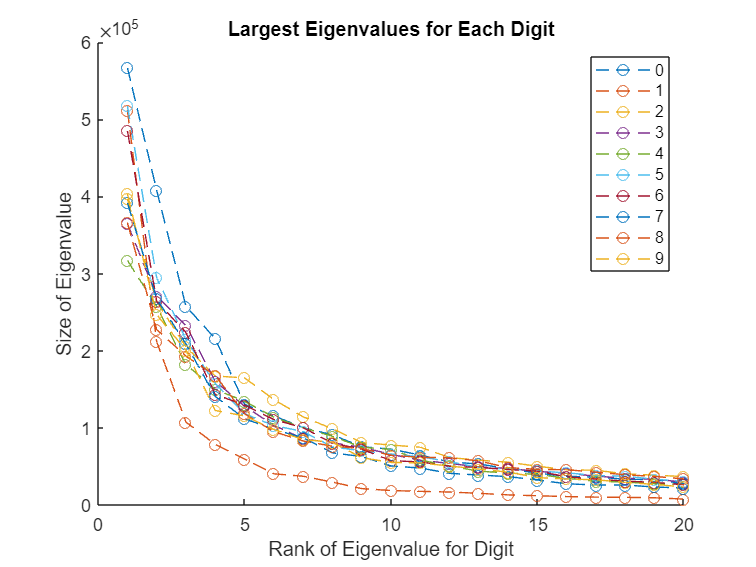

figure,
hold on;
for i = (1:10)
    eigens = sort(eig(covs(:,:,i)),'descend');    %sort the eigenvalues
    plot((1:20),eigens(1:20),'o--');
end
legend('0','1','2','3','4','5','6','7','8','9','Location','northeast')
title("Largest Eigenvalues for Each Digit")
ylabel("Size of Eigenvalue");
xlabel("Rank of Eigenvalue for Digit");
hold off;

How many “principal” / significant modes of variation (i.e., number of “large” eigenvalues) do you find, for each digit ? Are the significant modes of variation equal to 282 or far less ? Why ? 

We can clearly observe in the graph that the trend is same over all the digits; there are very few eigenvalues that are of significance. Roughly speaking, only the last 5 eigenvalues are >1 for most of the digits. This tells us that the significant modes of variation are approximately 5 in number. This number is far too less than 784 ($28^2$) and hence tell us that there are very few significant modes of variation in the images. The eigenvalues essentially capture the features in the images which vary the most over the set of images, and this number being less implies that there are not many ways in which the images can significantly differ from each other. Most of the information in the images can be considered by these **"principal" **eigenvectors. The small eigenvalues (close to 0) mostly correspond to noise and can be disregarded. Considering more of the larger eigenvalues would mean "considering more detailed features". 

• (5 points) For each digit, show the 3 images side by side: 

(i) µ − √ λ1v1, (ii) µ, and (iii) µ + √ λ1v1,

 to show the principal mode of variation of the digits around their mean. Comment and justify what you observe. For a certain digit, say 1, what does the principal mode of variation tell you about how people write that digit ?

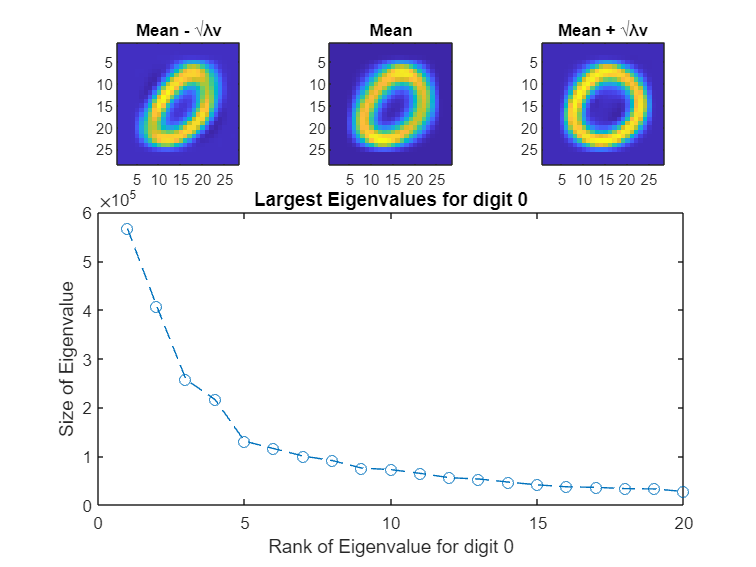

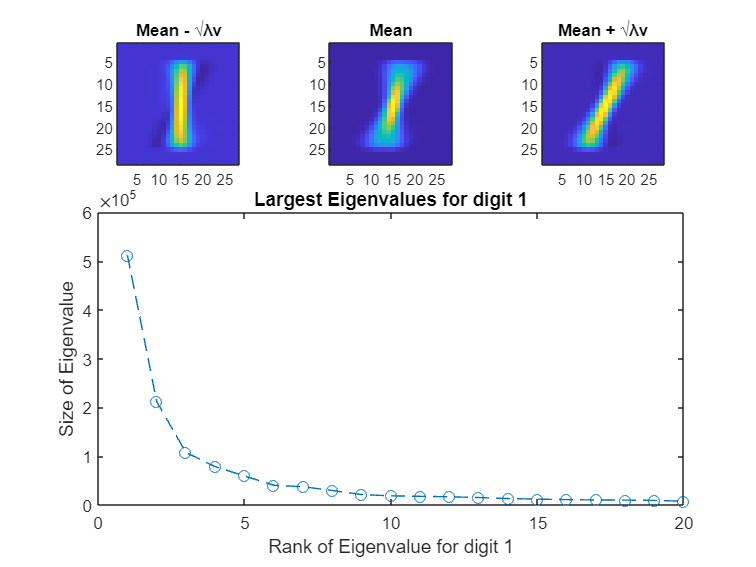

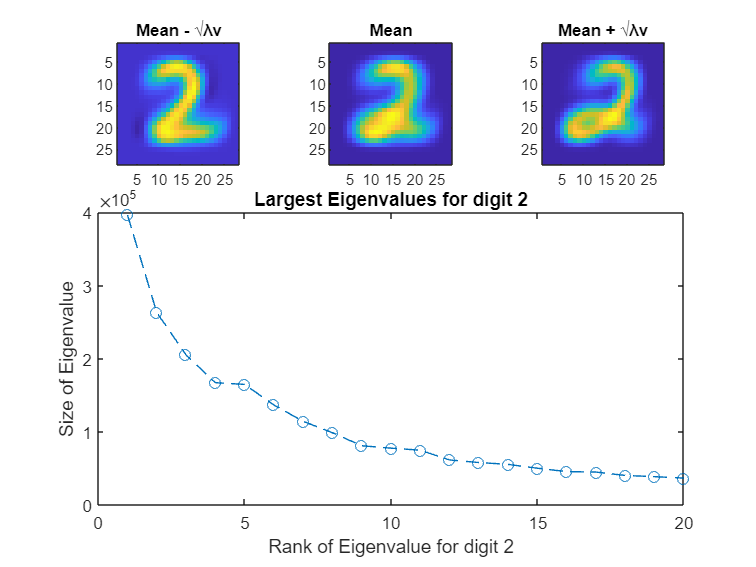

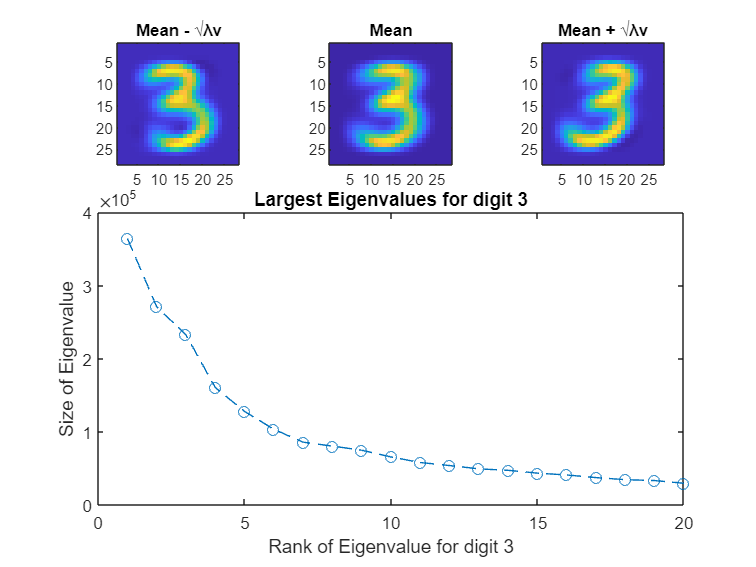

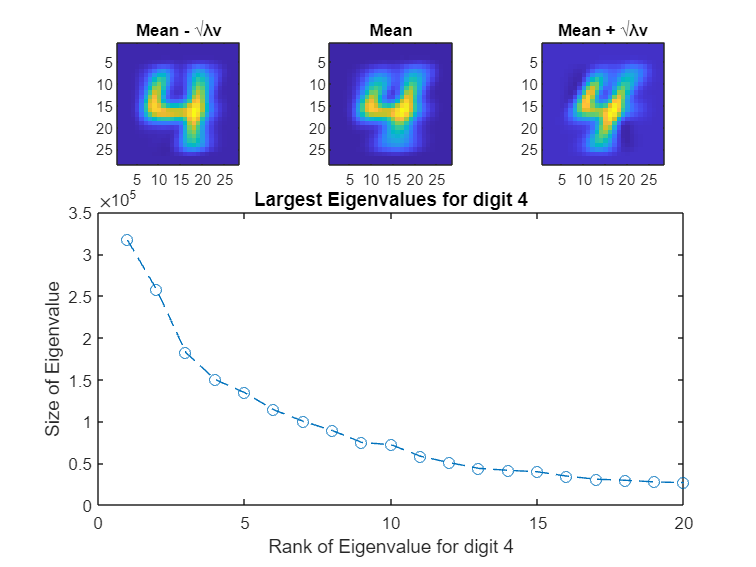

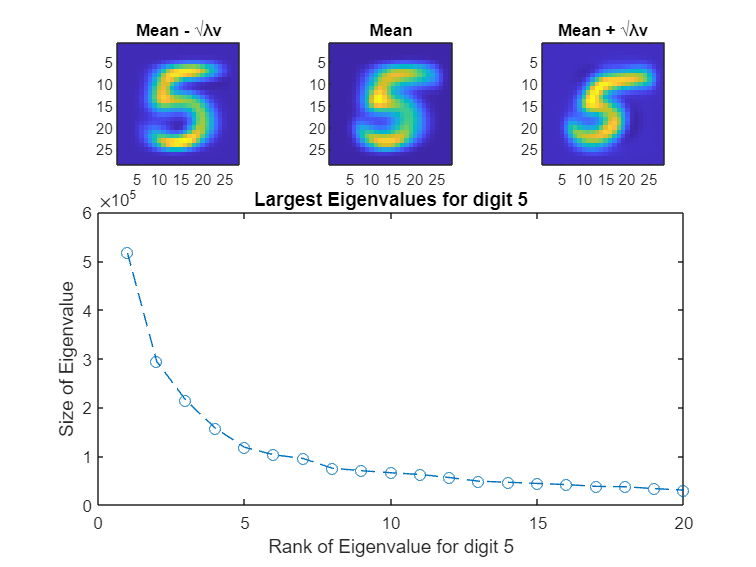

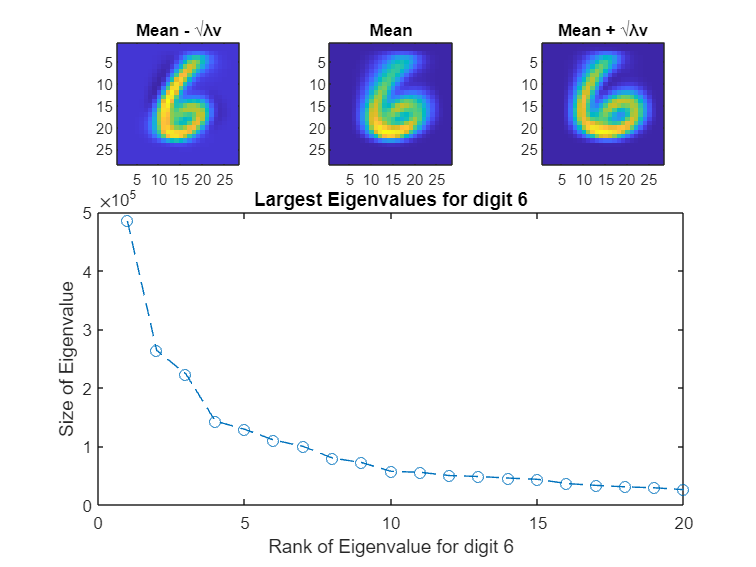

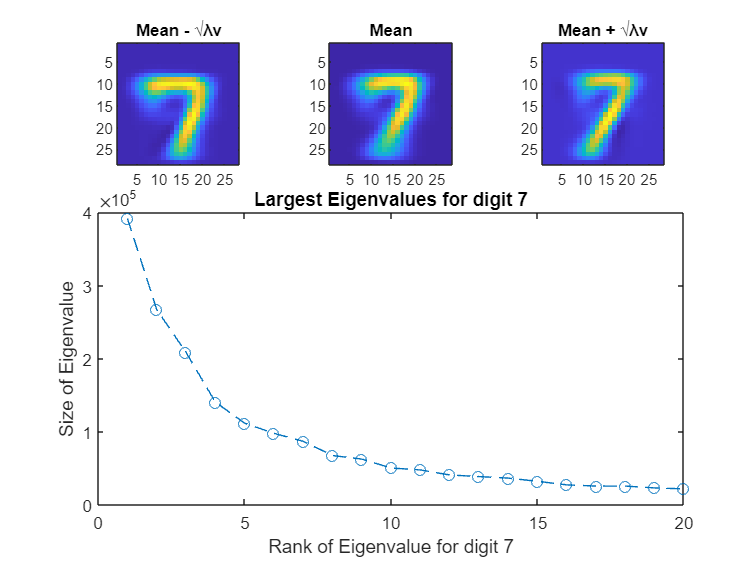

%sqrt(lambda1)v1 as a matrix is
lv = vectors*diag(sqrt(values));


for i =(1:10)
    
    figure,
    
    subplot(3,3,1);
    %nexttile
    imagesc(reshape(means(:,i)-lv(:,i),28,28));   %image of mean left shifted by principal eigenvector
    title("Mean - √λv")
    pbaspect([1,1,1])
    
    subplot(3,3,2);
    %nexttile
    imagesc(reshape(means(:,i),28,28));   %image of mean
    title("Mean");
    pbaspect([1,1,1])

    subplot(3,3,3);
    %nexttile
    imagesc(reshape(means(:,i)+lv(:,i),28,28));   %image of mean right shifted by principal eigenvector
    title("Mean + √λv")
    pbaspect([1,1,1])   

    subplot(3,3, 4:9);
    eigens = sort(eig(covs(:,:,i)),'descend');   %plot eigenvalues for each digit separately
    plot((1:20),eigens(1:20),'o--');
    xlabel("Rank of Eigenvalue for digit " + (i-1));
    ylabel("Size of Eigenvalue");
    title("Largest Eigenvalues for digit " + (i-1))
    
end

The images plotted here give us a rough idea of the ways(or more technically, the direction) in which images differ the most from their mean over the set of images(because PCA gives us the maximum variation eigenvectors). Let us consider the digit 1. We can see that the **mean** 1 is blurry and this means that people write 1 in a large variety of ways. Consider the image left and right to the mean, we observe that the differ from the mean the most in the direction of the slant of 1. This tells that the major difference in the **'1'** that people write is in the direction of the slant of '1'